# Class 17/09

#### 4.3.3 Axis et Titre

- Pour ajouter un titre: **title(**'montitre'**);**

- Pour ajouter le nom des axes: **xlabel(**'axe x'**)/ylabel(**'axe y'**);**

- Pour faire apparâitre des valeurs particuliers sur les axes: **xticks(**0:pi/4:2*pi**) **et **xticklabel(**{'0','pi/4','pi/2','3pi/4','pi','5pi/4','3pi/2','7pi/4','2pi'}**);**

- Pour spécifier les limites des axes: **xlim(**[xmin xmax]**) , ylim(**[ymin ymax]**), axis(**[xmin xmax ymin ymax]**)** 

x2 = linspace(0, 2*pi, 100);
y2 = cos(x2);
figure;
plot(x2, y2, Color="#24bf86", LineWidth=2);
xlabel('x');
ylabel('sin(x)');
xticks(0:pi/4:2*pi)
xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'})
axis([min(x2) max(x2) min(y2) max(y2)])
axis equal
grid on
hold on

#### 4.3.4 Légendes

- Pour ajouter une légende: **legend(**'leg1','leg2'**)**

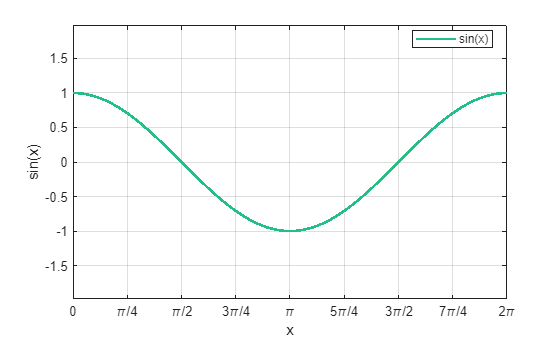

legend('sin(x)','Location','best')
hold off

**Exercise: Sur l'intervalle [0 1], tracer:**

- **La droite d'equation y = 2x+1 en pointillé rouge**

- **La droite d'equation x = 0.5 tout pleine vert**

- **10 carrés randomiques magenta**

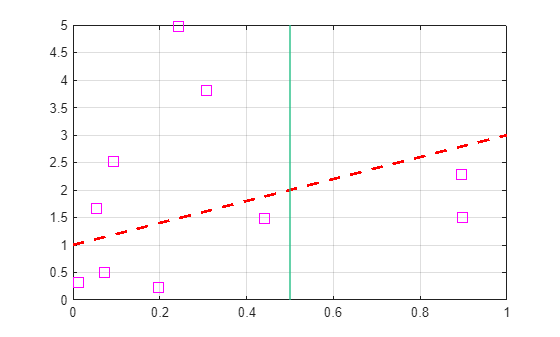

x1 = linspace(0,1,100);
y1 = ((2*x1) + 1);
figure;
plot(x1,y1,Color="r", LineStyle="--", LineWidth=2);
xlim([0 1])
ylim([0 5])
xline(0.5, Color = "#24bf86", LineWidth=2)
xSquares = rand(1, 10);
ySquares = rand(1, 10) *5;
hold on
scatter(xSquares, ySquares, 100, 'square','MarkerEdgeColor', 'magenta');
grid on
hold off

### 4.4 Subplot

Pour tracer plusieurs graphes sur une même figure, on utilise **subplot(**i,j,k**) **avec i,j le nombre de lignes et collones divisant la figure et k l'emplacement active

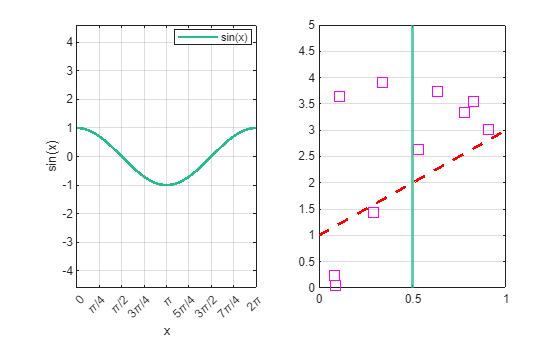

%example
figure;
subplot(1,2,1);
plot(x2, y2, Color="#24bf86", LineWidth=2);
xlabel('x');
ylabel('sin(x)');
xticks(0:pi/4:2*pi)
xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'})
axis([min(x2) max(x2) min(y2) max(y2)])
axis equal
grid on
hold on
legend('sin(x)','Location','best')
hold off
subplot(1,2,2);
plot(x1,y1,Color="r", LineStyle="--", LineWidth=2);
xlim([0 1])
ylim([0 5])
xline(0.5, Color = "#24bf86", LineWidth=2)
xSquares = rand(1, 10);
ySquares = rand(1, 10) *5;
hold on
scatter(xSquares, ySquares, 100, 'square','MarkerEdgeColor', 'magenta');
grid on
hold off

### 4.5 Autres Graphes

#### 4.5.1 plot3

Pour tracer une coube dans l'espace: **plot3(**x,y,z**)**

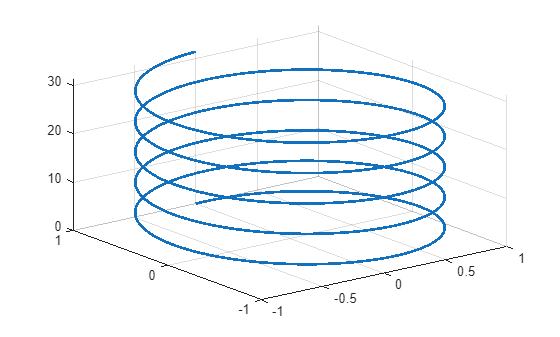

%example
t = linspace(0,10*pi,1000);
figure;
plot3(sin(t),cos(t),t, LineWidth=2);
grid on
hold off

#### 4.5.2 Logarithmique

- **loglog(x,y)**

- **semilogx(x,y)**

- **semilogy(x,y)**

#### **4.5.3 En vrac**

- **hist(y)**

- **bar(x,y)**

- **rose(t)**

### **4.6 Graph** de Surface

Pour tracer un graphe surfacique: **surf(X,Y,Z)** ou **mesh(**X,Y,Z**) **en définisant au préalable une grille sur un espace 2D avec **meshgrid**

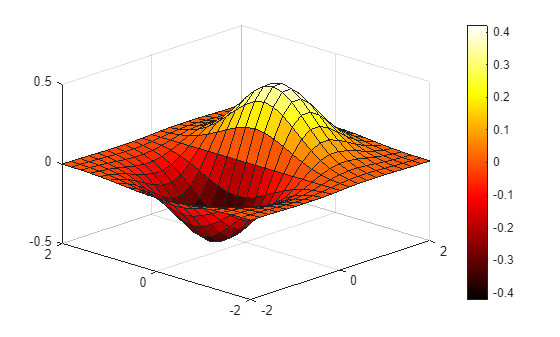

a = -2:0.2:2;
[X Y] = meshgrid(a, a);
Z = X.*exp(-X.^2-Y.^2);
figure;
surf(X,Y,Z)
colormap("hot")
colorbar;

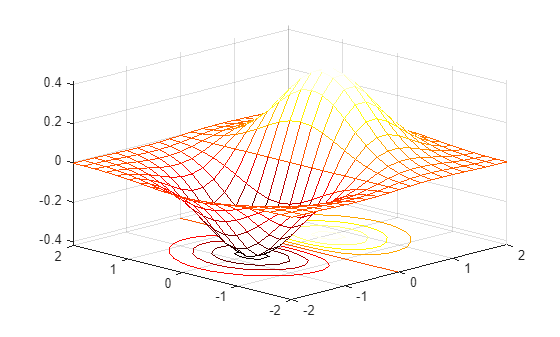

meshc(X,Y,Z)